# Math 244: MATLAB Assignment 3

### Name: 

### RUID:

### Date:

clear;
close all;
clc;

## 1. 

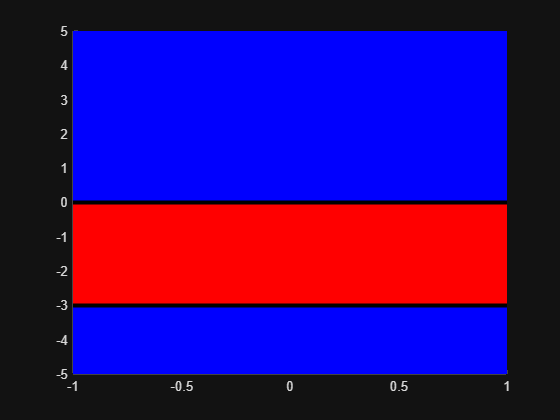

f = @(y) y.*(y+3);
phaseLine(f, -5, 5);

phaseLine makes a graph that colors areas between critical points blue if dy/dt > 0, and red if dy/dt < 0. Solutions are colored in black. This graph works exaclty as a phase line, but uses colors instead of arrows to display if a differential equation is increasing, decreasing, or is at a critical point.

## 2.

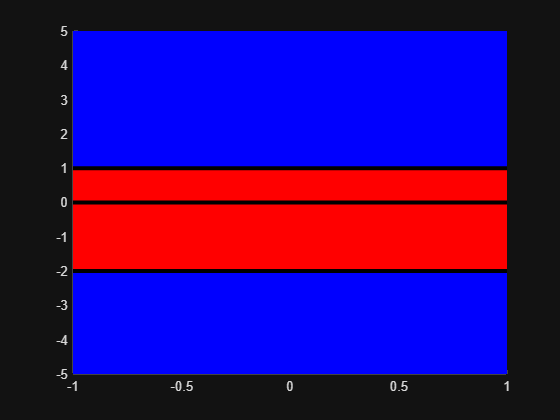

figure();
f = @(y) y.^2 .* (y+2) .* (y-1);
phaseLine(f, -5, 5);

% Phase line for the first equation

Unstable at y=1

Semi-Stable at y = 0

Asymptomatically stable at y = -2

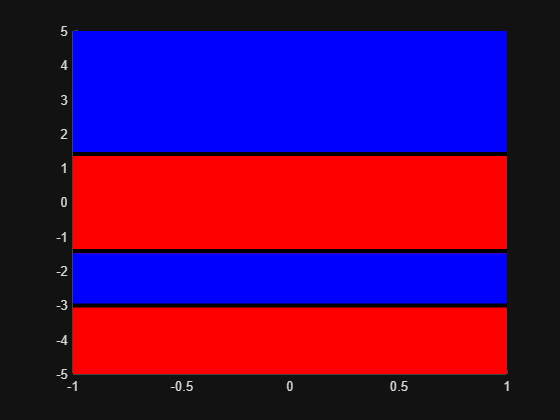

figure();
f = @(y) (y.^2-2) .* (y+3);
phaseLine(f, -5, 5);

% Phase line for the second equation

Unstable at y = 1.4

Asymptotically stable at y = -1.4

Unstable at y = -3

## 3.

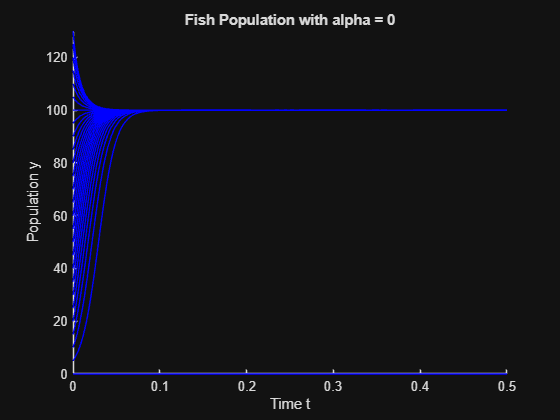


figure();
f = @(t,y) y .* (100-y);
t_min = 0;
t_max = 0.5;
y_min = 0;
y_max = 130;
t_0 = 0;
y_0 = [0:5:130];
col = 'b';
title(['Fish Population with alpha = 0']);
xlabel('Time t');
ylabel('Population y');
samplePlots244(f, t_min, t_max, y_min, y_max, t_0, y_0, col);

% alpha = 0 plot 

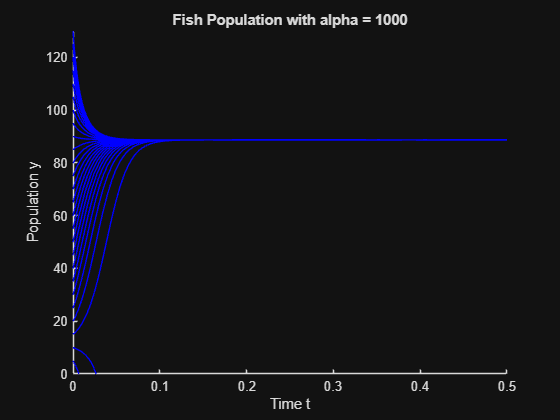

figure();
g = @(t, y) y .* (100-y) - 1000;
samplePlots244(g, t_min, t_max, y_min, y_max, t_0, y_0, col);
title('Fish Population with alpha = 1000');
xlabel('Time t');
ylabel('Population y');

% alpyha = 1000 plot 

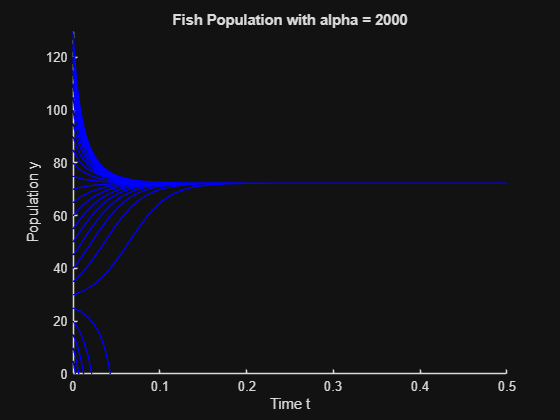

figure();
h = @(t, y) y .* (100-y) - 2000;
samplePlots244(h, t_min, t_max, y_min, y_max, t_0, y_0, col);
title('Fish Population with alpha = 2000');
xlabel('Time t');
ylabel('Population y');

% alpha = 2000 plot 

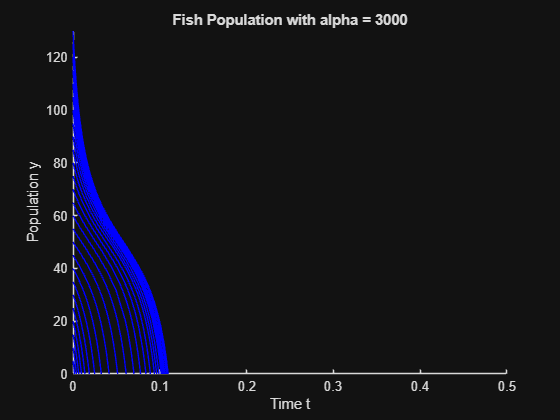

figure();
i = @(t, y) y .* (100-y) - 3000;
samplePlots244(i, t_min, t_max, y_min, y_max, t_0, y_0, col);
title('Fish Population with alpha = 3000');
xlabel('Time t');
ylabel('Population y');

% alpha = 3000 plot 

## 4. 

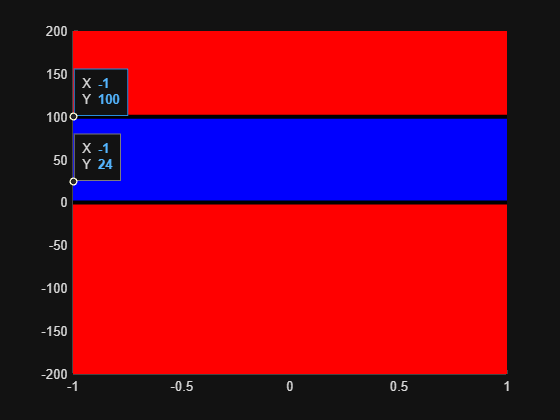

figure();
f = @(y) y .* (100-y);
phaseLine(f, -200, 200);

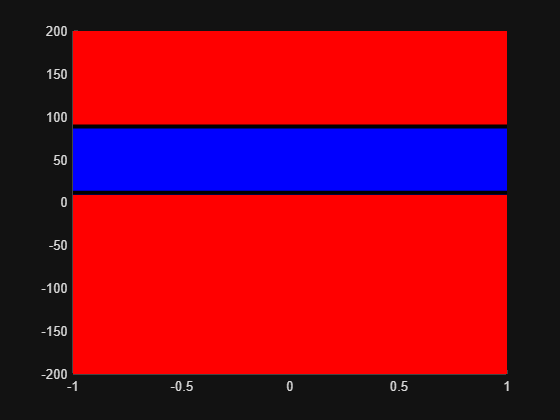

% Phase line for alpha = 0 

figure();
g = @(y) y.*(100-y) - 1000;
phaseLine(g, -200, 200);

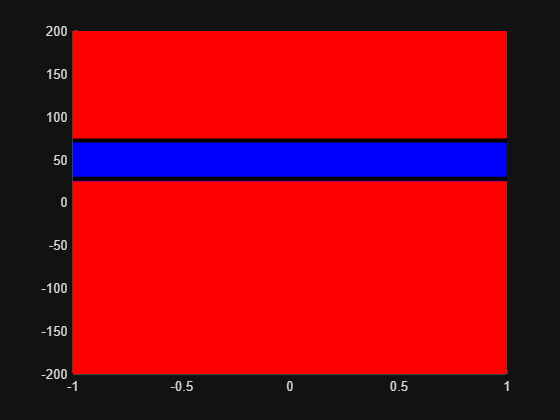

% Phase line for alpha = 1000 

figure();
h = @(y) y.*(100-y) - 2000;
phaseLine(h, -200, 200);

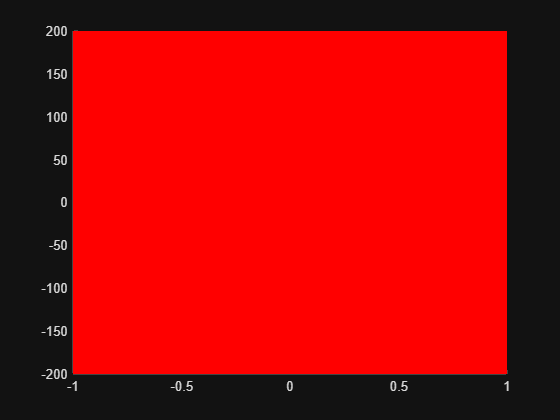

% Phase line for alpha = 2000 

figure();
i = @(y) y.*(100-y) - 3000;
phaseLine(i, -200, 200);

% Phase line for alpha = 3000



## 5. 

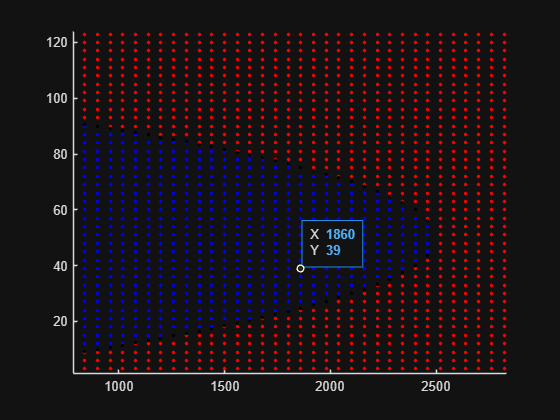

figure();
bifDiag244(@(a,y) y.*(100- y) - a, 0, 3000, 0, 150)

Alpha changes behavior at 2500, where no real solutions are available and the fish population goes extinct. We can find this by expanding the formula into the binomial y^2 - 100y - a and using the quadratic formula. Alpha goes into the 4ac rooted term and gives no real solution when 4*alpha > 100^2.